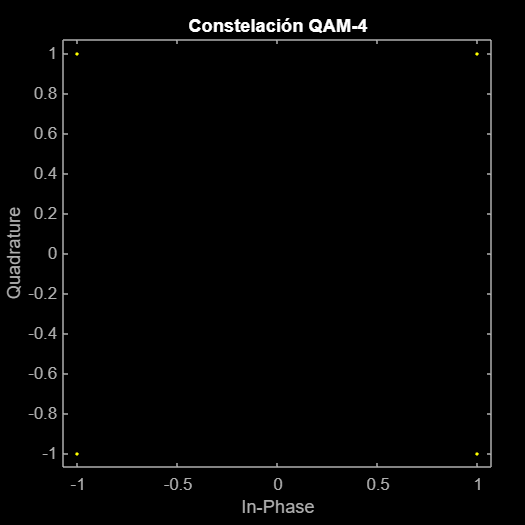

%IMPLEMENTACIÓN EN MATLAB DE UN PROCESADOR POLIFASE
clear all;
%Tenemos un canal idea( sin multitrayecto,ruido , ni atenuación)

%Primera parte, definimos distintas variables necesarias para el proceso:

%El filtro transmisor es SRRC (filtro de raíz de coseno alzado). Parametros
%de este filtro
span = 10; %numero de periodos
alfa = 0.25; %El valor es variable y va desde 0 a 1 que son los valores posibles que tiene alfa
M = 19; %factor de sobremuestreo del procesador
srrc = rcosdesign (alfa, span, M, 'sqrt'); %el span es la longitud del filtro en simbolos y M las muestras por simbolo

%Constelación, QAM:
%1-Parametros de la constelación
 
Nmodulacion = 4; %Vamos a hacer una Qam, para modificarla y tener un 16, por ejemplo, solo habría que modificar este parametro
bitsporsimbolo = log2(Nmodulacion);

%Proceso para generar la constelación QAM
simbolosQAM = qammod(0:Nmodulacion-1, Nmodulacion);

% Generamos una secuencia de bits aleatorios
numbits = 1000; % Número total de bits
bits = randi([0 1], 1, numbits);

% Convertir los bits en símbolos QAM
QAM = zeros(1, numbits/bitsporsimbolo);
for i = 1:bitsporsimbolo:numbits
    idx = bi2de(bits(i:i+bitsporsimbolo-1), 'left-msb') + 1;
    QAM((i+bitsporsimbolo-1)/bitsporsimbolo) = simbolosQAM(idx);
end

% Graficar la constelación de los símbolos modulados
scatterplot(QAM);
title(['Constelación QAM-', num2str(Nmodulacion)]);

Esta es la señal de entrada del transmisor

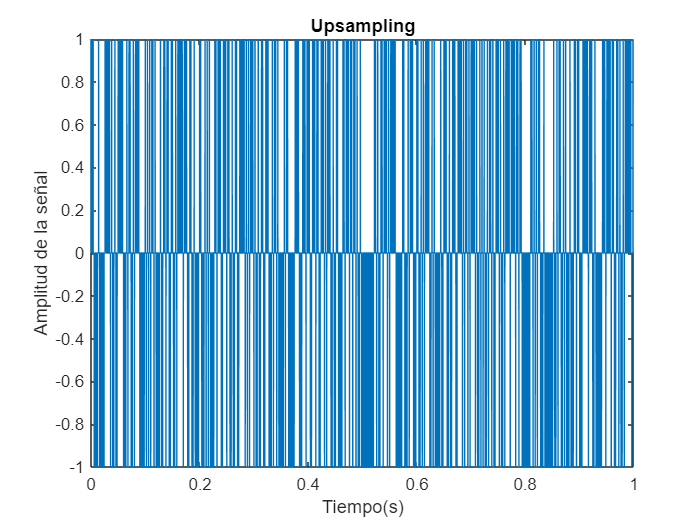

%Transmisor Monofase:

%Primer paso en el monofase, realizamos el upsampling:
%La señal de entrada es la  QAM anterior.

upsampling = upsample(QAM, M);
tupsampling= linspace(0,1,length(upsampling));
figure;
plot(tupsampling, real(upsampling));
xlabel('Tiempo(s)');
ylabel('Amplitud de la señal');
title('Upsampling');

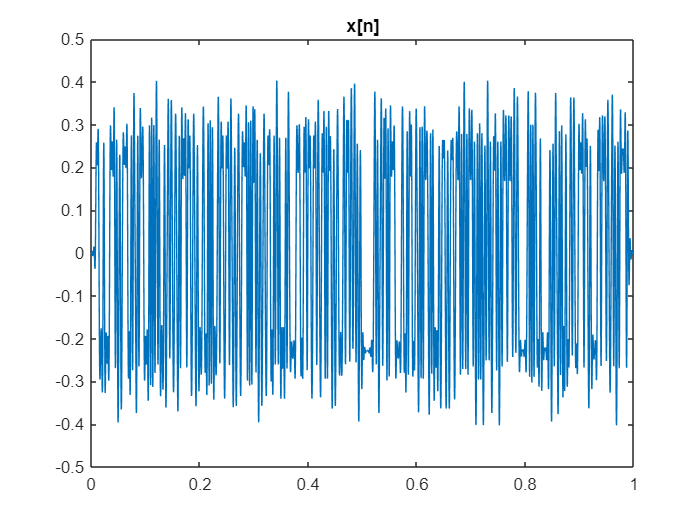

%Segundo paso, aplicamos el filtro SRRC anteriormente descrito:
filtrada = conv(upsampling ,srrc); %convolucionamos el filtro con la señal despues del upsampling
tfiltrada = linspace(0,1, length(filtrada));
%Mostramos la salida del monofase de transmisión:
figure;
plot(tfiltrada, real(filtrada));
title('x[n]');

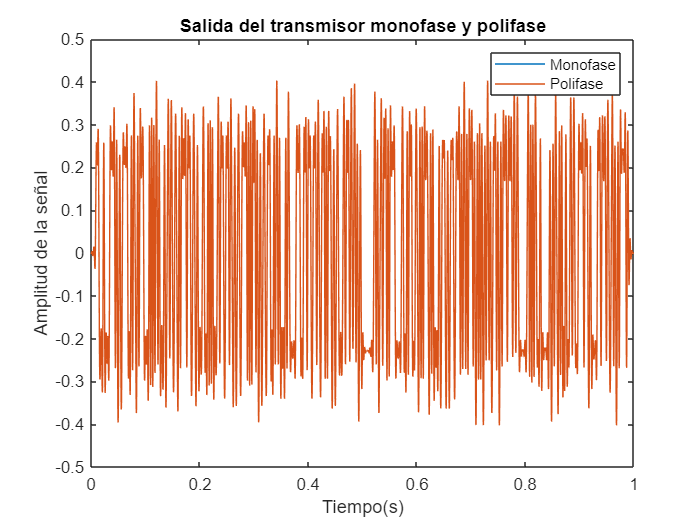

%Polifase de transmisión:
%Ahora los datos los enviamos por M-1 ramas, es decir, por 18 ramas

amp =  zeros(1, M-1); % Creamos un vector de M-1 ceros para añadir al filtro tx

filtrotx = [srrc, amp]; %Ese vector lo añadimos al final del fitro srrc, así podremos aplicar un filtro distinto a cada rama
for i= 1:M
%Primer paso, mandamos el flujo de datos por las 18 ramas
    ramas(i,:) = QAM;
    %Segundo paso, realizamos la convolución con el filtro transmisor SRRC
    %Creamos el filtro para cada rama
    filtro = filtrotx(i:M:end); 
    %En el polifase teorico tenemos gtxl[k] en este punto y en el monofase
    %gtx[19k+l], por lo tanto, en el polifase necesitamos un filtro 19
    %veces mas pequeño, así lo obtenemos
    convolucion (i,:)= conv(ramas(i,:), filtro);
    %Tercer paso, upsampling:
    upsamplingpoli(i,:) = upsample(convolucion(i,:), M);
    %Cuarto paso, retardamos la señal, usando circshift:
    if i >=2 %la primera rama no hay que retardarla
        senalretardada(i,:) = circshift (upsamplingpoli(i,:),i-1);
    end %end if
    if i == 1

        senalretardada(i,:) = upsamplingpoli(i,:);
    end % end if
   

end %end for
%Quinto paso, sumamos todas las ramas:

senalfinal = sum(senalretardada,1); 

tf = linspace (0,1, length(senalfinal));
plot(tfiltrada, real(filtrada));
hold on
plot(tf, real(senalfinal));
xlabel('Tiempo(s)');
ylabel('Amplitud de la señal');
title('Salida del transmisor monofase y polifase');
legend('Monofase', 'Polifase'); 
hold off

%Para comparar si ambas salidas son iguales hallamos su norma
normatx = norm(senalfinal - filtrada)

normatx = 5.3568e-15

La norma, basicamente, calcula la diferencia entre cada elemento del vector uno por uno (haciendo el cuadrado de cada vector para tener en cuenta a la vez parte real e imaginaria) , al ser tan pequeña la norma, es que practicamente no hay diferencia entre ambos vectores y podemos concluir que son iguales y, por tanto, que las salidas del monofase y polifase son iguales. Por lo tanto, la salidas teóricas del monofase y polifase para los filtros transmisores son correctas.

%%MODULACIÓN
%Primero, tenemos que tener en cuenta que tanto en tx como rx , la mínima
%frecuencia de portadora es de 1/T, ya que en caso contrario habrá solape
%entre las muestras.
% La frecuencia máxima sen tx será fc= M/2T - 1/T, por lo tanto:
Ttx= 1/1000; %periodo de simbolos (de transmisión, se corresponde con T en la formula de arriba)
%con el período de simbolos que hemos definido y la fc maxima que hemos dicho más arriba podemos usar el siguiente valor como fc:

fctx = 1000;
tmod= linspace(0,1, length(senalfinal));
Tmod= tmod*Ttx;
exponencialmod = exp (1j* 2*pi*fctx *Tmod);
%modulamos
mod= senalfinal.*exponencialmod; 
%resampleamos la señal para adaptarnos a la entrada del demodulador
entrada = 40; %Tasa a la entrada del demodulador
res = resample(mod, entrada, M);

%DEMODULACIÓN:
Trx = 1/1000; % periodo de símbolo de recepción (se corresponde con T de la formula de debajo)
%en rx la fc máxima será de : fc =L/4T- 1/2T, por lo tanto, podemos definir
%la siguiente 
fcrx= 1000;
tdemod= linspace(0,1,length(res));
Tdemod = tdemod*Trx;
L = 10; %factor de downsampling
exponencial = exp(-1j * 2 * pi *fcrx *Tdemod);
%Demodulamos
demod = res.*exponencial;


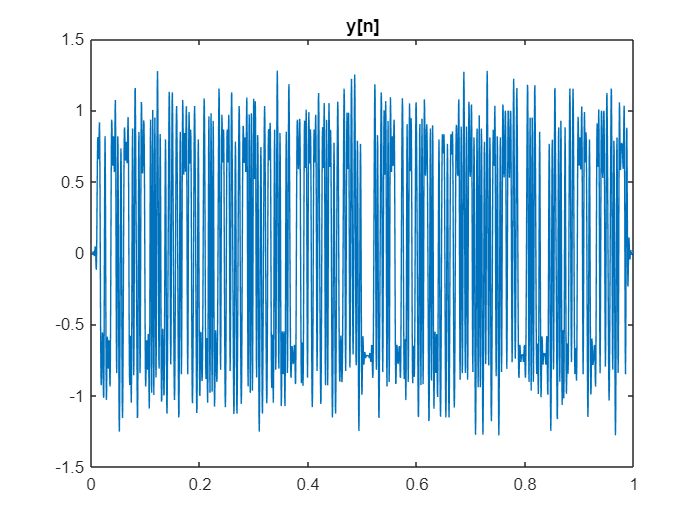

%Empezamos con el receptor:
%RECEPTOR MONOFASE:
srrcrx = rcosdesign (alfa, span, L, 'sqrt');  
%filtro srrc para recepción,el factor alfa es el definido más arriba
%Primer paso, filto rx:

filtrorx = conv(demod,srrcrx);

%Segundo paso, downsampling
downsamplingrx = downsample(filtrorx,L);
monofaserx = downsamplingrx;
%Mostramos la salida del monofase de transmisión:
tmonofaserx = linspace (0,1, length(monofaserx));
figure;
plot(tmonofaserx, real(monofaserx));
title('y[n]');

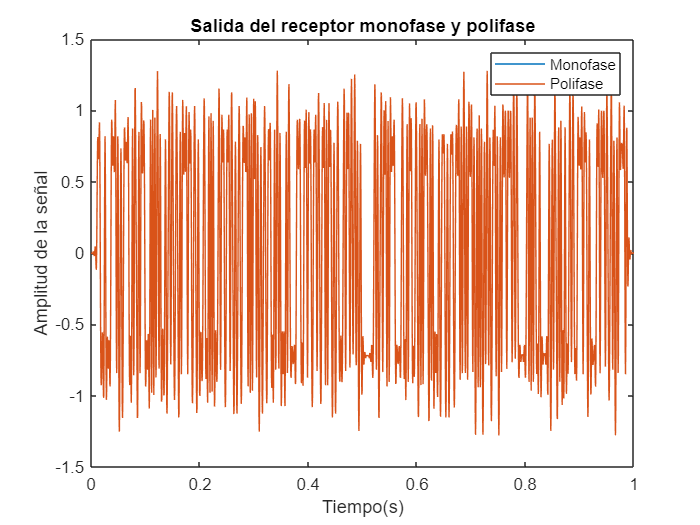

%Receptor Polifase:
%Filtro que vamos a aplicar en cada rama
amprx =  zeros(1, L-1); % Creamos un vector de L-1 ceros

filtrorxpolifase = [srrcrx, amprx]; %Ese vector lo añadimos al final del fitro srrc, así podremos aplicar un filtro distinto a cada rama
for j= 1:L
%Primer paso, mandamos el flujo de datos por las 9 ramas
    ramasrx(j,:) = demod;
    %Segundo paso, retardamos
    if j>=2
        senalretardadarx (j,:) =circshift(ramasrx(j,:), j-1);
    end %end if

    if j == 1
        senalretardadarx (j,:) =  ramasrx(j,:);
    end %end if
    %Tercer paso, downsampling
    downsampling (j,:) = downsample(senalretardadarx(j,:),L);
    %Cuarto paso, convolucion con el filtro rx:
    %Creamos el filtro para cada rama
    filtroL = filtrorxpolifase(j:L:end); 
    convolucionrx (j,:)= conv(downsampling (j,:), filtroL);
    

end %end for
%Quinto paso, juntamos todas las ramas:

salidapolifaserx = sum(convolucionrx,1); 

tpolifaserx = linspace (0,1, length(salidapolifaserx));

plot(tmonofaserx, real(monofaserx));
hold on
plot(tpolifaserx, real(salidapolifaserx));
xlabel('Tiempo(s)');
ylabel('Amplitud de la señal');
title('Salida del receptor monofase y polifase');
legend('Monofase', 'Polifase'); 
hold off

%Volvemos a hallar la norma
normarx = norm(salidapolifaserx-monofaserx)

normarx = 1.5520e-14

Al igual que en transmisión hallamos la norma para ver las diferencias entre la salida del monofase y el polifase y volvemos a concluir que no hay diferencias. Por lo tanto, la salidas teóricas del monofase y polifase para los filtros receptores son correctas.